rng(0)
xdim = 4; % solve for n-state system
ydim = 2;
A = 0.2*rand(xdim);
C = rand(ydim,xdim);
%eig(A)
N = 1e3;
x0 = rand(xdim,1);
w = 0.1*randn(xdim,N);
v = 0.1*randn(ydim,size(w,2));


Y = zeros(2,size(w,ydim));
x = x0;
for k = 1:size(w,2)
  Y(:,k) = C*x+v(:,k);
  x = A*x + w(:,k);
end
%sys = ss(A,eye(2),C,0*eye(2,2),2e-5);
%y = lsim(sys,w');


Construct Hankel Matrix

s = 50; % number of block rows; this should be long enough to capture plan dynamics, but not too long
% in other words, choose a length which is long enough to observe
% interesting behaviors in the autocorrelation

Yhp = [];
Yhf = [];
for k = 1:s
  Yhp = [Yhp;...
    Y(k:(N-2*s+k-1))];%#ok
  Yhf = [Yhf;...
    Y((s+k):(N-s+k-1))];%#ok
end

Solve for E[Yhf|Yhp]

O = Yhf*Yhp'/(Yhp*Yhp')*Yhp;

Compute the observability matrix

% figure
% bar(svd(O))
xestdim = xdim;
[U,S,V] = svds(O,xestdim); % solve for SVD. we're cheating and using the state dimension of the actual system
OM = U*sqrt(S);

Compute A and C matrices


Chat = OM((1:ydim),:);

Ahat = OM(1:(size(OM,1)-ydim),:)\OM((1+ydim):size(OM,1),:);
% eig(Ahat)
% eig(A)

Compare

Since the estimated system matrices are non-unique, the state of the estimated will in general be a linear transformation of the original state

The disturbance, w, would likewise need to be transformed for a direct comparison

Instead, I do the comparison in two ways:

- Compute the KF estimate of the measurements

- Compute the equivalent initial condition for my estimated system and compare the transient of the estimated system vs the actual system 

KF

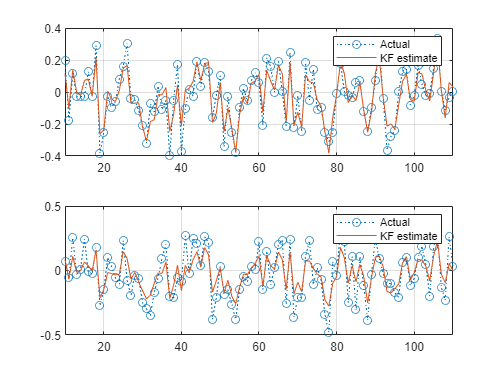

SANITYCHECK = false;
if SANITYCHECK
  Ahat = 0.2*eye(xdim);
  Chat = randn(ydim,xdim);
end
syshat = ss(Ahat,eye(xdim),Chat,zeros(ydim,xdim),1); % note that the "B" matrix is identity since it is being used for process noise w
KF = kalman(syshat,0.1^2*eye(xdim),0.1^2*eye(ydim));
Yhat = lsim(KF,Y);

figure
for plotnum = 1:2
  subplot(2,1,plotnum)
  plot(Y(plotnum,:),'o:');
  hold on
  plot(Yhat(:,plotnum));
  legend("Actual","KF estimate")
  xlim([0,100]+10);
  grid on;
end

Initial condition settling

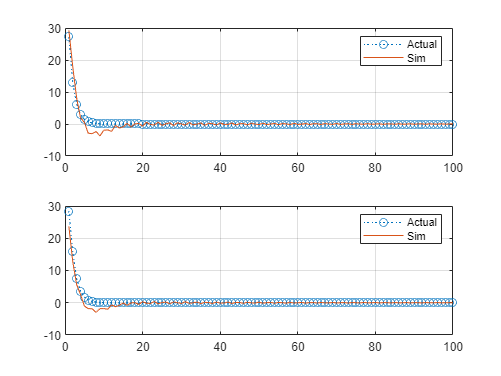

T1 = obsv(A,C)\obsv(Ahat,Chat);
T2 = obsv(Ahat,Chat)\obsv(A,C);

x = 10*ones(xdim,1);
xhat = T2*x;
Yi = zeros(ydim,100);
Yihat = zeros(ydim,100);
for k = 1:100
  Yi(:,k) = C*x;
  x = A*x;

  Yihat(:,k) = Chat*xhat;
  xhat = Ahat*xhat;

end


figure
for plotnum = 1:2
  subplot(2,1,plotnum)
  plot(Yi(plotnum,:),'o:');
  hold on
  plot(Yihat(plotnum,:));
  legend("Actual","Sim"); grid on;
end